%% ============================================================
% SINGLE-PHOTON SCANNING CAMERA
% V2 - SPARSE PHOTON RECONSTRUCTION
%
% Purpose:
% Develop a reconstruction algorithm capable of recovering
% spatial information from photon-limited, noisy measurements.
%
% Optical model:
%
% Gaussian star field
%       ↓
% Telescope focal plane
%       ↓
% 4.2 um fibre spatial sampling
%       ↓
% Photon-limited measurement
%       ↓
% SPCM-AQRH model
%       ↓
% Dark counts + Poisson noise
%       ↓
% Reconstruction algorithm
%       ↓
% Reconstructed SPC image
%
% ============================================================

clear;
clc;
close all;


%% ============================================================
% 1. TELESCOPE AND FIBRE
% ============================================================

FOCAL_LENGTH = 6459e-3;       % Telescope focal length [m]

FIBRE_DIAMETER = 4.2e-6;      % Fibre diameter [m]

FIBRE_DIAMETER_UM = 4.2;      % Fibre diameter [um]


% Approximate angular sampling

angularSamplingRad = ...
    FIBRE_DIAMETER / FOCAL_LENGTH;

angularSamplingArcsec = ...
    angularSamplingRad * (180/pi) * 3600;


fprintf('Fibre angular sampling = %.4f arcsec\n', ...
    angularSamplingArcsec);

Fibre angular sampling = 0.1341 arcsec


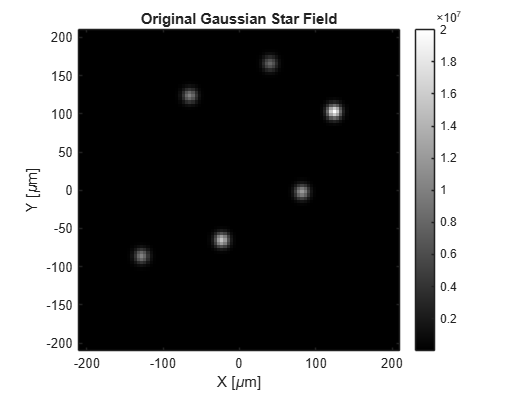



%% ============================================================
% 2. FOCAL PLANE
% ============================================================

IMAGE_WIDTH  = 100;
IMAGE_HEIGHT = 100;

PIXEL_SIZE_UM = FIBRE_DIAMETER_UM;


x = ((1:IMAGE_WIDTH) - (IMAGE_WIDTH+1)/2) ...
    * PIXEL_SIZE_UM;

y = ((1:IMAGE_HEIGHT) - (IMAGE_HEIGHT+1)/2) ...
    * PIXEL_SIZE_UM;

[X,Y] = meshgrid(x,y);


%% ============================================================
% 3. CREATE GAUSSIAN STAR FIELD
% ============================================================

starField = zeros(IMAGE_HEIGHT,IMAGE_WIDTH);


% [X position, Y position, brightness]

stars = [
    20, 30, 10e6;
    45, 35, 15e6;
    70, 50, 12e6;
    80, 75, 20e6;
    35, 80, 10e6;
    60, 90, 8e6
];


% Gaussian PSF width

PSF_SIGMA_PIXELS = 1.5;

PSF_SIGMA_UM = ...
    PSF_SIGMA_PIXELS * PIXEL_SIZE_UM;


% Generate Gaussian stars

for k = 1:size(stars,1)

    starX = ...
        (stars(k,1) - (IMAGE_WIDTH+1)/2) ...
        * PIXEL_SIZE_UM;

    starY = ...
        (stars(k,2) - (IMAGE_HEIGHT+1)/2) ...
        * PIXEL_SIZE_UM;

    brightness = stars(k,3);


    gaussianStar = brightness * ...
        exp( ...
        -((X-starX).^2 + (Y-starY).^2) ...
        /(2*PSF_SIGMA_UM^2) );


    starField = starField + gaussianStar;

end


%% ============================================================
% 4. DISPLAY ORIGINAL IMAGE
% ============================================================

figure;

imagesc(x,y,starField);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

xlabel('X [\mum]');
ylabel('Y [\mum]');

title('Original Gaussian Star Field');



%% ============================================================
% 5. DETECTOR PARAMETERS
% ============================================================

PDE = 0.65;

DARK_COUNT_RATE = 101;       % Measured dark count [Hz]

INTEGRATION_TIME = 0.1;      % Measurement time [seconds]


% Photon-limited scaling factor
%
% Reduce this value to make the imaging problem harder.
%
% 1.0  = high photon level
% 0.1  = lower photon level
% 0.01 = strongly photon limited

PHOTON_SCALE = 0.01;


%% ============================================================
% 6. SCAN PARAMETERS
% ============================================================

Nx = 50;
Ny = 50;


scanX = linspace(min(x),max(x),Nx);
scanY = linspace(min(y),max(y),Ny);


% Raw measured photon counts

rawCounts = zeros(Ny,Nx);


% Corrected counts

correctedCounts = zeros(Ny,Nx);


%% ============================================================
% 7. GENERATE PHOTON-LIMITED MEASUREMENTS
% ============================================================

fprintf('\n');
fprintf('Generating photon-limited measurements...\n');

Generating photon-limited measurements...


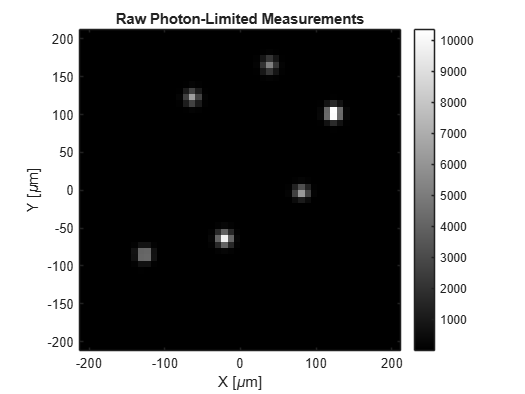



for j = 1:Ny

    for i = 1:Nx


        %% ----------------------------------------------------
        % Current fibre position
        % -----------------------------------------------------

        fibreX = scanX(i);
        fibreY = scanY(j);


        %% ----------------------------------------------------
        % Find nearest focal-plane position
        % -----------------------------------------------------

        [~,ix] = min(abs(x-fibreX));
        [~,iy] = min(abs(y-fibreY));


        %% ----------------------------------------------------
        % Approximate fibre spatial sample
        % -----------------------------------------------------

        localSignal = starField(iy,ix);


        %% ----------------------------------------------------
        % Convert optical signal to photon rate
        % -----------------------------------------------------

        photonRate = ...
            localSignal * PHOTON_SCALE;


        %% ----------------------------------------------------
        % Expected detected photons
        % -----------------------------------------------------

        expectedSignal = ...
            photonRate * PDE * INTEGRATION_TIME;


        %% ----------------------------------------------------
        % Expected dark counts
        % -----------------------------------------------------

        expectedDark = ...
            DARK_COUNT_RATE * INTEGRATION_TIME;


        %% ----------------------------------------------------
        % Total expected count
        % -----------------------------------------------------

        expectedTotal = ...
            expectedSignal + expectedDark;


        %% ----------------------------------------------------
        % Poisson photon-counting noise
        % -----------------------------------------------------

        measuredCount = ...
            poissrnd(expectedTotal);


        %% ----------------------------------------------------
        % Store raw measurement
        % -----------------------------------------------------

        rawCounts(j,i) = measuredCount;


    end

end


%% ============================================================
% 8. DISPLAY RAW PHOTON COUNTS
% ============================================================

figure;

imagesc(scanX,scanY,rawCounts);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

xlabel('X [\mum]');
ylabel('Y [\mum]');

title('Raw Photon-Limited Measurements');

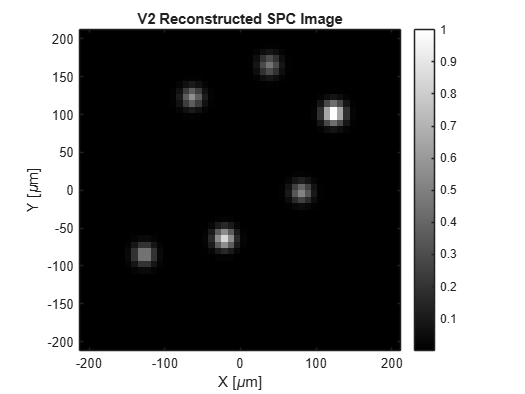



%% ============================================================
% 9. DARK COUNT CORRECTION
% ============================================================

expectedDarkCounts = ...
    DARK_COUNT_RATE * INTEGRATION_TIME;


correctedCounts = ...
    rawCounts - expectedDarkCounts;


% Counts cannot be negative

correctedCounts(correctedCounts < 0) = 0;


%% ============================================================
% 10. CONVERT TO ESTIMATED PHOTON RATE
% ============================================================

estimatedPhotonRate = ...
    correctedCounts ./ ...
    (PDE * INTEGRATION_TIME);


%% ============================================================
% 11. SPATIAL RECONSTRUCTION
% ============================================================

% Start with corrected photon-rate image

reconstructedImage = estimatedPhotonRate;


%% ============================================================
% 12. SIMPLE SPATIAL REGULARISATION
% ============================================================

% A small Gaussian filter reduces random photon-counting noise
% while retaining the spatial structure of the stars.

FILTER_SIGMA = 0.8;

filterSize = 5;

[xFilter,yFilter] = meshgrid( ...
    -floor(filterSize/2):floor(filterSize/2), ...
    -floor(filterSize/2):floor(filterSize/2));


gaussianFilter = ...
    exp(-(xFilter.^2 + yFilter.^2) ...
    /(2*FILTER_SIGMA^2));


gaussianFilter = ...
    gaussianFilter / sum(gaussianFilter(:));


reconstructedImage = ...
    conv2(reconstructedImage, ...
    gaussianFilter,'same');


%% ============================================================
% 13. NORMALISE RECONSTRUCTED IMAGE
% ============================================================

reconstructedNormalised = ...
    reconstructedImage ./ ...
    max(reconstructedImage(:));


%% ============================================================
% 14. DISPLAY RECONSTRUCTED IMAGE
% ============================================================

figure;

imagesc(scanX,scanY,reconstructedNormalised);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

xlabel('X [\mum]');
ylabel('Y [\mum]');

title('V2 Reconstructed SPC Image');

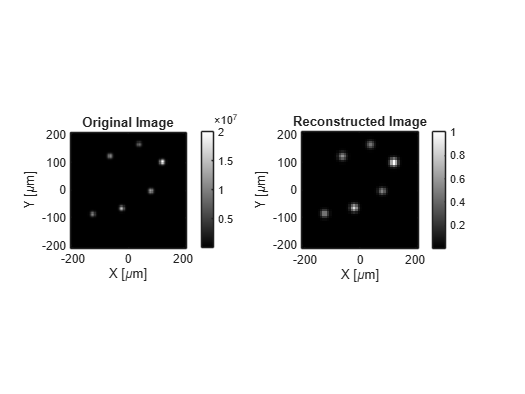



%% ============================================================
% 15. COMPARE ORIGINAL AND RECONSTRUCTED IMAGE
% ============================================================

figure;


subplot(1,2,1);

imagesc(x,y,starField);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('Original Image');

xlabel('X [\mum]');
ylabel('Y [\mum]');


subplot(1,2,2);

imagesc(scanX,scanY,reconstructedNormalised);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('Reconstructed Image');

xlabel('X [\mum]');
ylabel('Y [\mum]');

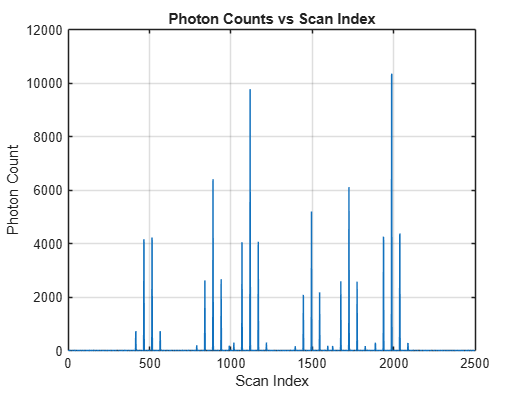



%% ============================================================
% 16. COUNTS VS SCAN INDEX
% ============================================================

figure;

plot(rawCounts(:));

xlabel('Scan Index');

ylabel('Photon Count');

title('Photon Counts vs Scan Index');

grid on;



%% ============================================================
% 17. CALCULATE SIMPLE IMAGE QUALITY METRICS
% ============================================================

% Resize original image to reconstruction size

originalForComparison = ...
    imresize(starField,[Ny,Nx]);


% Normalise

originalForComparison = ...
    originalForComparison ./ ...
    max(originalForComparison(:));


reconstructedForComparison = ...
    reconstructedNormalised;


% Root Mean Square Error

RMSE = sqrt( ...
    mean( ...
    (originalForComparison(:) - ...
    reconstructedForComparison(:)).^2 ) );


% Correlation coefficient

correlationMatrix = corrcoef( ...
    originalForComparison(:), ...
    reconstructedForComparison(:));


correlationCoefficient = ...
    correlationMatrix(1,2);


%% ============================================================
% 18. RESULTS
% ============================================================

fprintf('\n');
fprintf('============================================\n');

fprintf('V2 SPARSE PHOTON RECONSTRUCTION\n');

V2 SPARSE PHOTON RECONSTRUCTION


fprintf('============================================\n');


fprintf('Telescope focal length: %.3f mm\n', ...
    FOCAL_LENGTH*1000);

Telescope focal length: 6459.000 mm



fprintf('Fibre diameter: %.1f um\n', ...
    FIBRE_DIAMETER_UM);

Fibre diameter: 4.2 um



fprintf('Angular sampling: %.4f arcsec\n', ...
    angularSamplingArcsec);

Angular sampling: 0.1341 arcsec



fprintf('PDE: %.0f %%\n',PDE*100);

PDE: 65 %



fprintf('Dark count rate: %.1f Hz\n', ...
    DARK_COUNT_RATE);

Dark count rate: 101.0 Hz



fprintf('Integration time: %.3f s\n', ...
    INTEGRATION_TIME);

Integration time: 0.100 s



fprintf('Photon scale: %.4f\n', ...
    PHOTON_SCALE);

Photon scale: 0.0100



fprintf('Scan size: %d x %d\n',Nx,Ny);

Scan size: 50 x 50



fprintf('Total measurements: %d\n',Nx*Ny);

Total measurements: 2500



fprintf('\n');

fprintf('Reconstruction RMSE: %.5f\n',RMSE);

Reconstruction RMSE: 0.02855



fprintf('Image correlation: %.4f\n', ...
    correlationCoefficient);

Image correlation: 0.9186



fprintf('============================================\n');



%% ============================================================
% 19. SAVE V2 DATA
% ============================================================

save('SPC_Sparse_Reconstruction_V2.mat', ...
    'starField', ...
    'rawCounts', ...
    'correctedCounts', ...
    'reconstructedImage', ...
    'reconstructedNormalised', ...
    'scanX', ...
    'scanY', ...
    'Nx', ...
    'Ny', ...
    'PDE', ...
    'DARK_COUNT_RATE', ...
    'INTEGRATION_TIME', ...
    'PHOTON_SCALE', ...
    'RMSE', ...
    'correlationCoefficient');


fprintf('\nV2 data saved.\n');


V2 data saved.
